# Preparing Data for Training

We prepare the downloaded images for training. For that we do not need to bring all the data in at once as it would occupy a lot of memory.  We can do that efficiently by using datastore and applying augmentation to make it sutiable for training.

## ImageDataStore

We will create a reference to the folder which contains all the labels including images. That way we would not bring all the images at once in MATLAB. This script should be saved in the folder containing FlowerImages folder where we downloaded the data initially

Flowerds = imageDatastore("FlowerImages/","IncludeSubfolders",true,"LabelSource","foldernames")

Flowerds =   ImageDatastore with properties:

                       Files: {
                              ' .../Documents/MATLAB/FlowerImages/alpine sea holly/image_06969.jpg';
                              ' .../Documents/MATLAB/FlowerImages/alpine sea holly/image_06970.jpg';
                              ' .../Documents/MATLAB/FlowerImages/alpine sea holly/image_06971.jpg'
                               ... and 8186 more
                              }
                     Folders: {
                              '/Users/phasuwut/Documents/MATLAB/FlowerImages'
                              }
                      Labels: [alpine sea holly; alpine sea holly; alpine sea holly ... and 8186 more categorical]
    AlternateFileSystemRoots: {}
                    ReadSize: 1
      SupportedOutputFormats: ["png"    "jpg"    "jpeg"    "tif"    "tiff"]
         DefaultOutputFormat: "png"
              

## Training and Validation set

We have a total of 8183 images with each label containing at least 40 images. We will divide the data into training and validation set with a proportion of 90 to 10. We will have atleast 4 images in each label for testing which we can increase by creating an augmented data set.

[imtrain,imval] = splitEachLabel(Flowerds,0.9)

imtrain =   ImageDatastore with properties:

                       Files: {
                              ' .../Documents/MATLAB/FlowerImages/alpine sea holly/image_06969.jpg';
                              ' .../Documents/MATLAB/FlowerImages/alpine sea holly/image_06970.jpg';
                              ' .../Documents/MATLAB/FlowerImages/alpine sea holly/image_06971.jpg'
                               ... and 7370 more
                              }
                     Folders: {
                              '/Users/phasuwut/Documents/MATLAB/FlowerImages'
                              }
                      Labels: [alpine sea holly; alpine sea holly; alpine sea holly ... and 7370 more categorical]
    AlternateFileSystemRoots: {}
                    ReadSize: 1
      SupportedOutputFormats: ["png"    "jpg"    "jpeg"    "tif"    "tiff"]
         DefaultOutputFormat: "png"
               

imval =   ImageDatastore with properties:

                       Files: {
                              ' .../Documents/MATLAB/FlowerImages/alpine sea holly/image_08085.jpg';
                              ' .../Documents/MATLAB/FlowerImages/alpine sea holly/image_08086.jpg';
                              ' .../Documents/MATLAB/FlowerImages/alpine sea holly/image_08087.jpg'
                               ... and 813 more
                              }
                     Folders: {
                              '/Users/phasuwut/Documents/MATLAB/FlowerImages'
                              }
                      Labels: [alpine sea holly; alpine sea holly; alpine sea holly ... and 813 more categorical]
    AlternateFileSystemRoots: {}
                    ReadSize: 1
      SupportedOutputFormats: ["png"    "jpg"    "jpeg"    "tif"    "tiff"]
         DefaultOutputFormat: "png"
                   

## Augment Training Images

As a rule of thumb, we do not train the network on exact same images in every epoch therefore we ease the process of modifying the images for the entire training by using augmentation. For this purpose we create augmented image data store which takes in the datastore reference to training set. This function will perform the augmenation (modification) to images seemlessly when the network is being trained.

Even if the modification to images is not desired, augmentedImageDatastore can be used to rectify the size of the images on the go as per network demands

auds = augmentedImageDatastore([224 224],imtrain,'DataAugmentation', ...
 imageDataAugmenter("RandRotation",[-180 180],"RandXReflection",true))

auds =   augmentedImageDatastore with properties:

             NumObservations: 7373
                       Files: {7373×1 cell}
    AlternateFileSystemRoots: {}
               MiniBatchSize: 128
            DataAugmentation: [1×1 imageDataAugmenter]
          ColorPreprocessing: 'none'
                  OutputSize: [224 224]
              OutputSizeMode: 'resize'
        DispatchInBackground: 0


### Total Number of Samples for each label

Number of samples for each label

[num,~,ic] = unique(imtrain.Labels);

a_table = table(num,accumarray(ic,1))

a_table = 102×2 table
           num            Var2
    __________________    ____

    alpine sea holly       39 
    anthurium              95 
    artichoke              70 
    azalea                 86 
    ball moss              41 
    balloon flower         44 
    barbeton daisy        114 
    bearded iris           49 
    bee balm               59 
    bird of paradise       77 
    bishop of llandaff     98 
    black-eyed susan       49 
    blackberry lily        43 
    blanket flower         44 
    bolero deep blue       36 
    bougainvillea         115 



disp(['Minimum number of training images in a label: ' num2str(min(a_table.Var2))])

Minimum number of training images in a label: 36


## Augmenting Validation Set

The purpose of augmenting validation set of images to increase the number of images for validation so that we have more than 10 images for each label. In this case we load all the images in the MATLAB memory. We will use this data for validation during training.

valset = [readall(augmentedImageDatastore([224 224],imval))
 readall(augmentedImageDatastore([224 224],imval,'DataAugmentation', ...
 imageDataAugmenter("RandRotation",[-180 180])))]

valset = 1632×2 table
          input              response    
    _________________    ________________

    {224×224×3 uint8}    alpine sea holly
    {224×224×3 uint8}    alpine sea holly
    {224×224×3 uint8}    alpine sea holly
    {224×224×3 uint8}    alpine sea holly
    {224×224×3 uint8}    anthurium       
    {224×224×3 uint8}    anthurium       
    {224×224×3 uint8}    anthurium       
    {224×224×3 uint8}    anthurium       
    {224×224×3 uint8}    anthurium       
    {224×224×3 uint8}    anthurium       
    {224×224×3 uint8}    anthurium       
    {224×224×3 uint8}    anthurium       
    {224×224×3 uint8}    anthurium       
    {224×224×3 uint8}    anthurium       
    {224×224×3 uint8}    artichoke       
    {224×224×3 uint8}    artichoke       


## Number of Samples in Validation Set

[num,~,ic] = unique(valset.response);

a_table = table(num,accumarray(ic,1))

a_table = 102×2 table
           num            Var2
    __________________    ____

    alpine sea holly        8 
    anthurium              20 
    artichoke              16 
    azalea                 20 
    ball moss              10 
    balloon flower         10 
    barbeton daisy         26 
    bearded iris           10 
    bee balm               14 
    bird of paradise       16 
    bishop of llandaff     22 
    black-eyed susan       10 
    blackberry lily        10 
    blanket flower         10 
    bolero deep blue        8 
    bougainvillea          26 



min(a_table.Var2)

ans = 8

# Preparing Network for Training

## Importing PreTrained Neural Network

Most pre-trained networks have been presented in a famous ImageNet Large Scale Visual Competition (ILSVRC). These networks are trained on 1000 categories each containing 1000 or so images. These networks are well trained in extracting different features of an image. So we transfer the weights of the initial layers of these networks and retrain on our set of images to classify accodingly.

 net2=googlenet

net2 =   DAGNetwork with properties:

         Layers: [144×1 nnet.cnn.layer.Layer]
    Connections: [170×2 table]
     InputNames: {'data'}
    OutputNames: {'output'}


(In case the network is not installed the commad will generate a link to install the network and then it needs to be rerun)

## Modifying the PreTrained Network Using Designer App

Once the network has been loaded open the app using the command where we will modify the network by changing the number of classes we are training the network on as well replace the last layer with a new one

For the clasification problem at hand, we have 102 flower categories when we want our network to distinguish so we will replace 

deepNetworkDesigner

## Modifying the PreTrained Network Programmatically

lgraph = layerGraph(net2)

lgraph =   LayerGraph with properties:

         Layers: [144×1 nnet.cnn.layer.Layer]
    Connections: [170×2 table]
     InputNames: {'data'}
    OutputNames: {'output'}


lgraph = replaceLayer(lgraph,'loss3-classifier',fullyConnectedLayer(102,"Name",'new-fc', ...
    'WeightLearnRateFactor',10,"BiasLearnRateFactor",10));


lgraph = replaceLayer(lgraph,'output',classificationLayer("Name",'newoutput'))

lgraph =   LayerGraph with properties:

         Layers: [144×1 nnet.cnn.layer.Layer]
    Connections: [170×2 table]
     InputNames: {'data'}
    OutputNames: {'newoutput'}


layers = lgraph.Layers

layers =   144×1 Layer array with layers:

     1   'data'                           Image Input                   224×224×3 images with 'zerocenter' normalization
     2   'conv1-7x7_s2'                   Convolution                   64 7×7×3 convolutions with stride [2  2] and padding [3  3  3  3]
     3   'conv1-relu_7x7'                 ReLU                          ReLU
     4   'pool1-3x3_s2'                   Max Pooling                   3×3 max pooling with stride [2  2] and padding [0  1  0  1]
     5   'pool1-norm1'                    Cross Channel Normalization   cross channel normalization with 5 channels per element
     6   'conv2-3x3_reduce'               Convolution                   64 1×1×64 convolutions with stride [1  1] and padding [0  0  0  0]
     7   'conv2-relu_3x3_reduce'          ReLU                          ReLU
     8   'conv2-3x3'                      Convolution               

connections = lgraph.Connections

connections = 170×2 table
             Source                      Destination        
    _________________________    ___________________________

    {'data'                 }    {'conv1-7x7_s2'           }
    {'conv1-7x7_s2'         }    {'conv1-relu_7x7'         }
    {'conv1-relu_7x7'       }    {'pool1-3x3_s2'           }
    {'pool1-3x3_s2'         }    {'pool1-norm1'            }
    {'pool1-norm1'          }    {'conv2-3x3_reduce'       }
    {'conv2-3x3_reduce'     }    {'conv2-relu_3x3_reduce'  }
    {'conv2-relu_3x3_reduce'}    {'conv2-3x3'              }
    {'conv2-3x3'            }    {'conv2-relu_3x3'         }
    {'conv2-relu_3x3'       }    {'conv2-norm2'            }
    {'conv2-norm2'          }    {'pool2-3x3_s2'           }
    {'pool2-3x3_s2'         }    {'inception_3a-1x1'       }
    {'pool2-3x3_s2'         }    {'inception_3a-3x3_reduce'}
    {'pool2-3x3_s2'         }    {'inception_3a-5x5

layers(1:10) = freezeWeights(layers(1:10))

layers =   144×1 Layer array with layers:

     1   'data'                           Image Input                   224×224×3 images with 'zerocenter' normalization
     2   'conv1-7x7_s2'                   Convolution                   64 7×7×3 convolutions with stride [2  2] and padding [3  3  3  3]
     3   'conv1-relu_7x7'                 ReLU                          ReLU
     4   'pool1-3x3_s2'                   Max Pooling                   3×3 max pooling with stride [2  2] and padding [0  1  0  1]
     5   'pool1-norm1'                    Cross Channel Normalization   cross channel normalization with 5 channels per element
     6   'conv2-3x3_reduce'               Convolution                   64 1×1×64 convolutions with stride [1  1] and padding [0  0  0  0]
     7   'conv2-relu_3x3_reduce'          ReLU                          ReLU
     8   'conv2-3x3'                      Convolution               

lgraph = createLgraphUsingConnections(layers,connections)

lgraph =   LayerGraph with properties:

         Layers: [144×1 nnet.cnn.layer.Layer]
    Connections: [170×2 table]
     InputNames: {'data'}
    OutputNames: {'newoutput'}


# Training Deep Neural Network

## Training Parameters

Once we have replaced the layers of networks and exported the modified network back, all that is left is setting up training parameters such as 

- Optimisation algorithm

- Batch of images to train back to back for one iteration

- Total number of Epochs

- Validation Data 

- Learning rate

miniBatchSize = 100;

options = trainingOptions('sgdm', ...
    'MiniBatchSize',miniBatchSize, ...
    'MaxEpochs',30, ...
    'InitialLearnRate',3e-4, ...
    'Shuffle','every-epoch', ...
    "ValidationFrequency", 50,...
    'ValidationData',valset, ...
    'Verbose',true, ...
    'Plots','training-progress')

options =   TrainingOptionsSGDM with properties:

                        Momentum: 0.9000
                InitialLearnRate: 3.0000e-04
               LearnRateSchedule: 'none'
             LearnRateDropFactor: 0.1000
             LearnRateDropPeriod: 10
                L2Regularization: 1.0000e-04
         GradientThresholdMethod: 'l2norm'
               GradientThreshold: Inf
                       MaxEpochs: 30
                   MiniBatchSize: 100
                         Verbose: 1
                VerboseFrequency: 50
                  ValidationData: [1632×2 table]
             ValidationFrequency: 50
              ValidationPatience: Inf
                         Shuffle: 'every-epoch'
                  CheckpointPath: ''
             CheckpointFrequency: 1
         CheckpointFrequencyUnit: 'epoch'
            ExecutionEnvironment: 'auto'
                      WorkerLoad: []
                     

## Train the network

It all comes together now, the data and training options we have arranged previously.

FlowerNet = trainNetwork(auds,lgraph_3,options)

Training on single CPU.
Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:02:48 |        1.00% |        1.10% |       6.9037 |       5.8323 |          0.0003 |


## Evaluate the network

Before deploying the network we will estimate the accuracy of this network by testing the image data set that we separated earlier.

[predicted,scores] = classify(FlowerNet,valset);
tableofscores = [table(predicted) array2table(scores,"VariableNames",categories(valset.response))]
nnz(predicted~=valset.response)/length(predicted) 

## Confusion Chart

Confusion chart can help in those categories which network is not able to classify properly so we can check our data and retrain the network with improved data to see if it rectifies the issue.

cm2 = confusionchart(string(valset.response(245:450)),string(predicted(245:450)),"RowSummary","row-normalized")

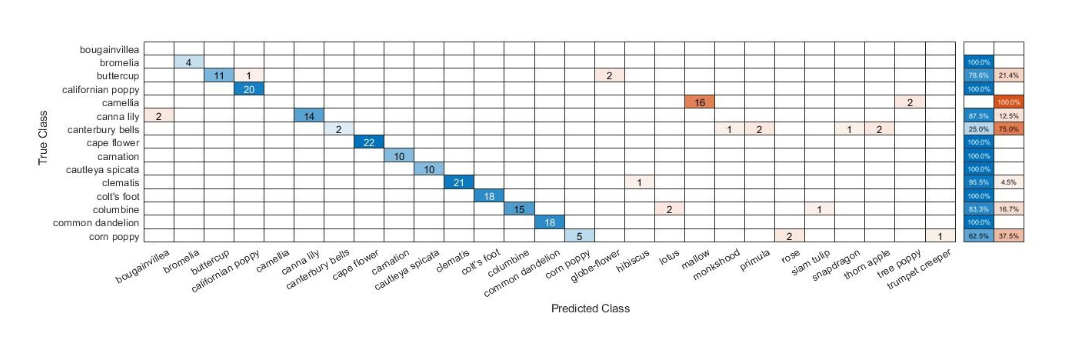

mostmisclassified(valset,predicted)

## Investigating Network Layers

While FlowerNet has many layers, I have selected an inception block that has convolution and pooling layers. 

### Using Activations

layer = "fc";
ind = find(valset.response == "camellia");
N = ind(6);
imshow(valset.input{N})

In convolution neural networks we can find out the activations of a particular conolutionals or pooling layers and understand how it is contributing to the classification. Activations give a visual pattern as a result of a filter applied to that image

acs1 = activations(FlowerNet,valset(N,:),layer);
size(acs1)
imshow(imresize(imtile(rescale(acs1)),[1000 1000]))

Besides giving us insight on the network, activations can help us find nearest neighbor of the sample and we can determine how that particular layer is working. It can give same colour neighbours, same background neighbours, or same shape neighbours and other features like that. It would change from layer to layer. However, there is little control on what each channel in a layer learns.

layer = "fc";
ind = find(valset.response == "camellia");
N = ind(6);
acs = activations(FlowerNet,auds,layer,"MiniBatchSize",1,"OutputAs","rows");
acs1 = activations(FlowerNet,valset(N,:),layer,"OutputAs","rows");

[idx, d] = knnsearch(acs, acs1, 'K', 5,"NSMethod","kdtree");   %machine learning algorithm of finding nearest neighbors
%idx(1) = [];
searchresults = readByIndex(auds,idx);

montage([valset.input(N); searchresults.input])
labelmontage(valset,searchresults,N)

### Using Deep Dream Image

DeepDreamImage feature helps understand us interpreting a networks visualisation of an image. Each layer has it's own way of looking at images in abstract sense

DD = deepDreamImage(FlowerNet,'fc',[20 23 57],"Verbose",false,"NumIterations",10,"ExecutionEnvironment","gpu"); %20-camellia, 23-capeflower,  57-mallow

imshow(imtile(DD(:,:,:,1:3),"BackgroundColor", [0 0.2 0.5]))
axis on
text(100,35,'Camellia',"FontSize",35); text(500,35,'Cape Flower',"FontSize",35); text(100,465,'Mallow',"FontSize",35)

## Deploying Network

We are going to implement this network in image batch processor that uploads images and classifies using the network we trained

imageBatchProcessor

function lgraph = createLgraphUsingConnections(layers,connections)

lgraph = layerGraph();
for i = 1:numel(layers)
    lgraph = addLayers(lgraph,layers(i));
end

for c = 1:size(connections,1)
    lgraph = connectLayers(lgraph,connections.Source{c},connections.Destination{c});
end

end

function layers = freezeWeights(layers)

for ii = 1:size(layers,1)
    props = properties(layers(ii));
    for p = 1:numel(props)
        propName = props{p};
        if ~isempty(regexp(propName, 'LearnRateFactor$', 'once'))
            layers(ii).(propName) = 0;
        end
    end
end

end

function labelmontage(valset,searchresults,N)
if height(searchresults) == 5
text(100,35,string(valset.response(N)),"FontSize",15); text(400,35,searchresults.response(1),"Color",[0.3 0.3 0.3],"FontSize",15); 
text(740,35,searchresults.response(2),"Color",[0.3 0.3 0.3],"FontSize",15); 
text(100,365,searchresults.response(3),"Color",[0.3 0.3 0.3],"FontSize",20); text(400,365,searchresults.response(4),"FontSize",20); 
text(780,365,searchresults.response(5),"Color",[0.3 0.3 0.3],"FontSize",20)

end
end

function mostmisclassified(valset,predicted)
%
v = valset.response(predicted~=valset.response);
[num,~,ic] = unique(v);
a_table = table(num,accumarray(ic,1));
[c,~,id] = unique(valset.response(ismember(valset.response,a_table.num(a_table.Var2>2))));
ac = table(c,accumarray(id,1));
b = bar3([a_table.Var2(a_table.Var2>2) ac.Var2]);
a = b.Parent;
a.XGrid = 'off';
a.YGrid = "off";
a.XTick = [];
b(1).FaceColor = [0.93,0.69,0.13];
b(1).FaceAlpha = 0.5;

b(2).FaceColor = [0.3 0.75 0.93];
b(2).FaceAlpha = 0.75;
yticks(1:length(c))
yticklabels(string(a_table.num(a_table.Var2>2)));
ytickangle(45);

view([-45.4 9.7])

legend('Misclassified Samples','Total Samples',"Location","best")
end